# Matpower Simulation

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a standard testbed. 

clear all
close all
clc
addpath('../src/');

rng(11);

We load the data.

define_constants;
noise_v_sd = 1e-5;
noise_i_sd = 1e-5;
mpc = loadcase('case6ww_modified');

We define useful constants and we derive the impedence matrix.

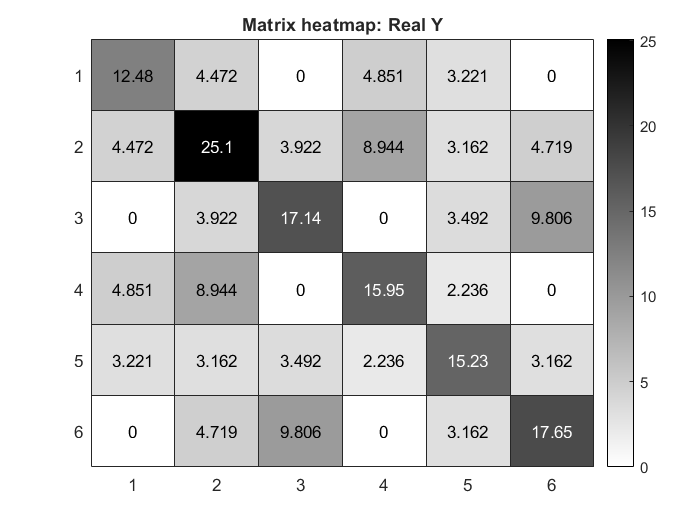

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))

ans = 2.2204e-16 + 1.7764e-15i

issymmetric(Y)

ans = logical
   1


Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles. [TODO]

samples = 50;
load_avg_pd = mpc.bus(load_mask, PD);
load_avg_qd = mpc.bus(load_mask, QD);
for i = 1:samples
    mpc.bus(load_mask, PD) = normrnd(load_avg_pd, 0.1 * load_avg_pd);
    mpc.bus(load_mask, QD) = normrnd(load_avg_qd, 0.1 * load_avg_qd);
    res = runpf(mpc);
    bus_phase = res.bus(:, VA) * pi / 180;
    bus_magnitude = res.bus(:, VM);
    bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
    load_pd(:, i) = res.bus(load_mask, PD);
    load_qd(:, i) = res.bus(load_mask, QD);
end


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.09 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    200.1             173.5
Loads              3     Load                   194.1             155.2
  Fixed            3       Fixed                194.1             155.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));
bus_current = Y * bus_voltage + ei;
bus_voltage = bus_voltage + ev;

Randomly generated voltages and currents for testing purpose only.

% bus_voltage = normrnd(100, 5, [n, samples]) + sqrt(-1) * normrnd(100, 5, [n, samples]);
% bus_current = Y * bus_voltage;

We visualize the evolution of the voltage and the current for a random node.

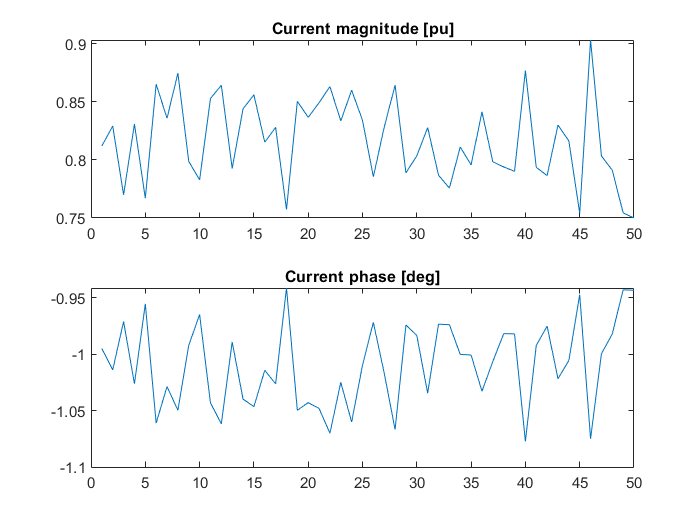

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title('Current magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title('Current phase [deg]');

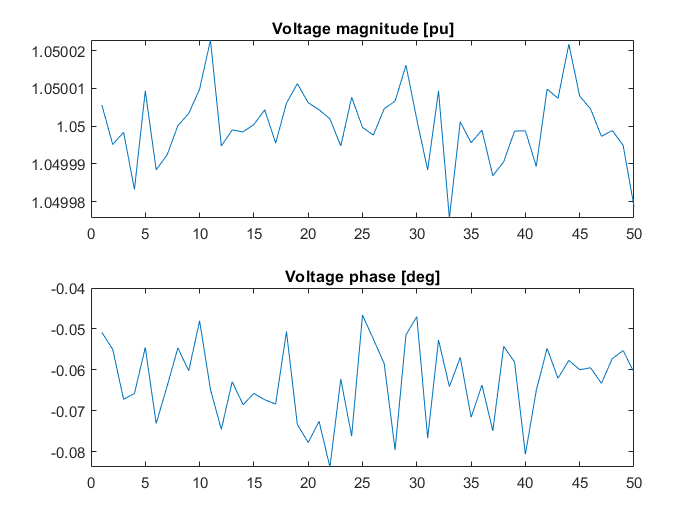

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_voltage));
title('Voltage magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_voltage));
title('Voltage phase [deg]');

Moreover, we check correlation between voltages

corr(bus_voltage')

ans =    1.0000 + 0.0000i  -0.0255 + 0.4083i  -0.0257 + 0.3463i  -0.1113 + 0.4397i   0.0123 + 0.3240i  -0.0069 + 0.3352i
  -0.0255 - 0.4083i   1.0000 + 0.0000i   0.9798 + 0.0116i   0.8757 + 0.0345i   0.9082 + 0.0837i   0.9309 + 0.1141i
  -0.0257 - 0.3463i   0.9798 - 0.0116i   1.0000 + 0.0000i   0.7936 - 0.0084i   0.9066 + 0.0844i   0.9650 + 0.1166i
  -0.1113 - 0.4397i   0.8757 - 0.0345i   0.7936 + 0.0084i   1.0000 + 0.0000i   0.7851 + 0.0304i   0.7168 + 0.0826i
   0.0123 - 0.3240i   0.9082 - 0.0837i   0.9066 - 0.0844i   0.7851 - 0.0304i   1.0000 + 0.0000i   0.8927 + 0.0213i
  -0.0069 - 0.3352i   0.9309 - 0.1141i   0.9650 - 0.1166i   0.7168 - 0.0826i   0.8927 - 0.0213i   1.0000 + 0.0000i


## Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

## OLS estimation

As a first benchmark, we estimate the admittance matrix using Ordinary Least.

Froebius norm for OLS is 0.091541
Max norm for OLS is 0.040323


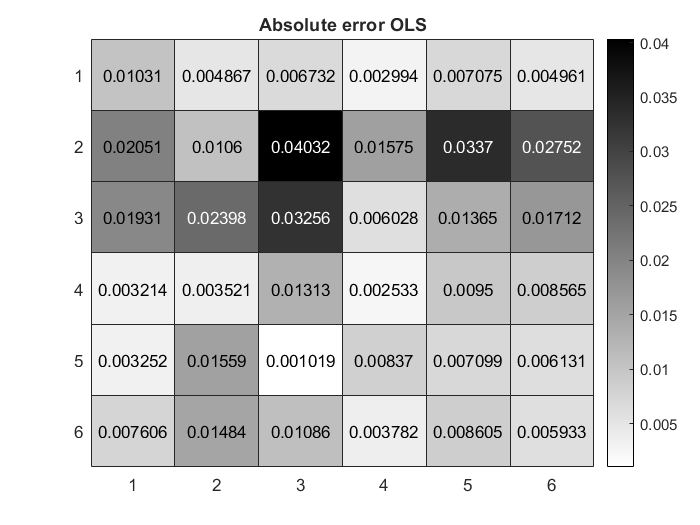

Y_hat_ols = conj(bus_voltage' \ bus_current');
error_metrics(Y, Y_hat_ols, 'OLS');

## Lasso Estimation

Following Ardakanian et al, we now resort to Lasso in order to peform the same estimation.

idx = 1:n;
nidx = setdiff(1:n,idx);
[Y22_est, Y12_est, Y11_est] = postprocessing(bus_voltage,bus_current,idx,nidx,Y);

Lasso method is being used...
best lambda is 0.0023101297
maximum absolute error is 0.038827
error norm is 0.10096
no. nonzero elements: 28
Thresholded lasso method with refitting is being used...
best lambda is 0.0001
maximum absolute error is 0.040323
error norm is 0.10141
no. nonzero elements: 28
Adaptive lasso method with OLS based weights is being used...
optimal gamma is 0.5
best lambda is 0.0001
maximum absolute error is 0.040279
error norm is 0.10139
no. nonzero elements: 28
Lasso outperformed other methods
Relative error (pct): 1.1084


Froebius norm for Lasso is 0.10096
Max norm for Lasso is 0.038827


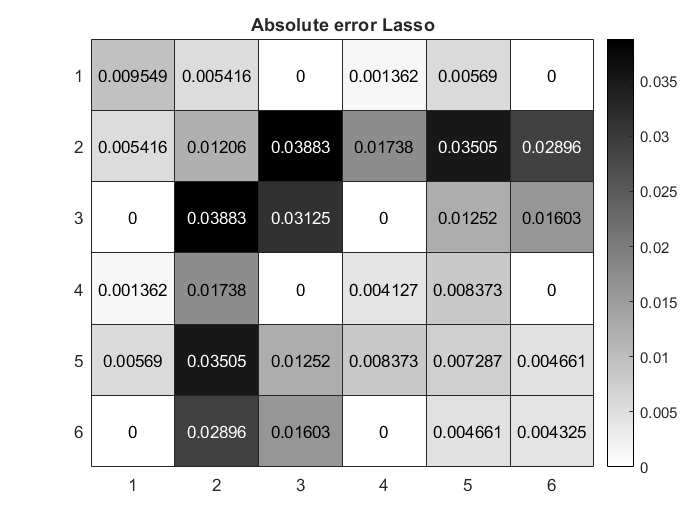

Y_hat_lasso  = [Y11_est Y12_est; Y12_est.' Y22_est];
error_metrics(Y, Y_hat_lasso, 'Lasso');

## RLS with symmetricity constraints (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

Froebius norm for RLS1 is 0.1018
Max norm for RLS1 is 0.036073


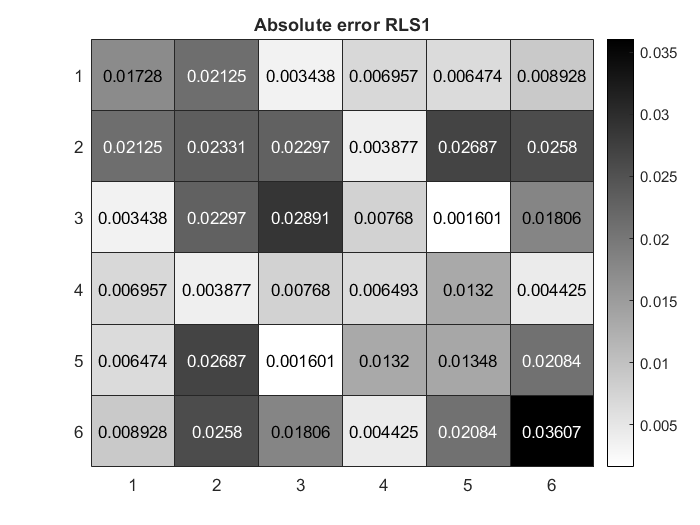

lambda = 0.7;
D = duplication_matrix(n);
[Y1_hat, Z1_hat] = estimate_rls(bus_voltage, bus_current, D, lambda);
error_metrics(Y, Y1_hat(:, :, end), 'RLS1');

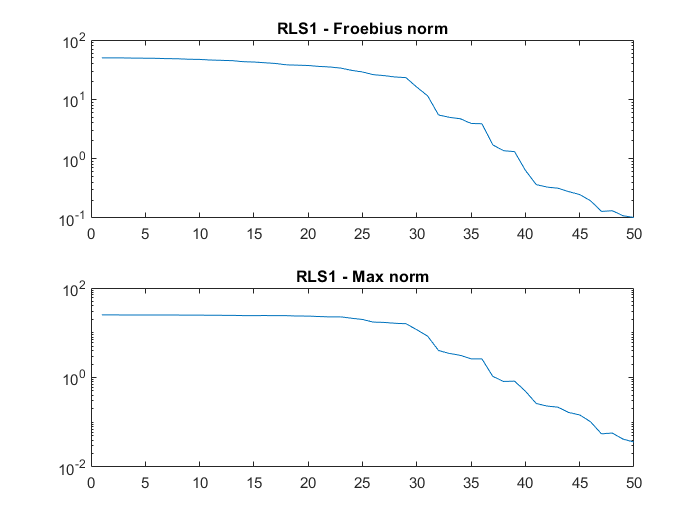

[rls1_foeb, rls1_max] = error_evolution(Y, Y1_hat, 'RLS1');

## RLS2

Then, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

Froebius norm for RLS2 is 0.092124
Max norm for RLS2 is 0.027908


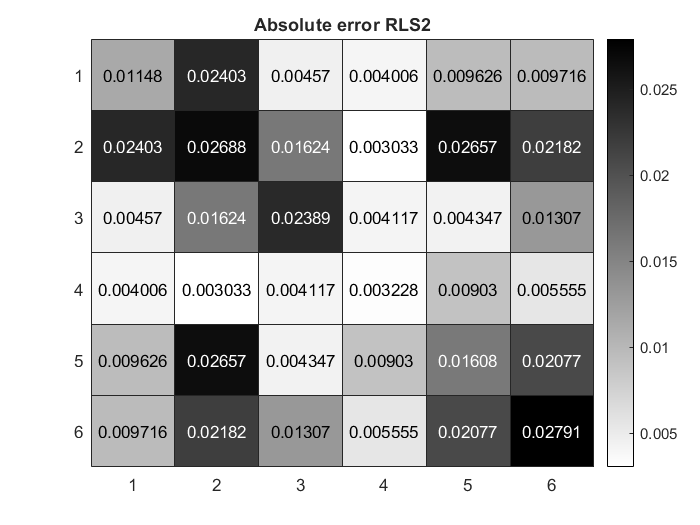

rls2_free_params = n*(n-1)/2;
Q = D * transformation_matrix(n);
[Y2_hat, Z2_hat] = estimate_rls(bus_voltage, bus_current, Q, lambda);
error_metrics(Y, Y2_hat(:, :, end), 'RLS2');

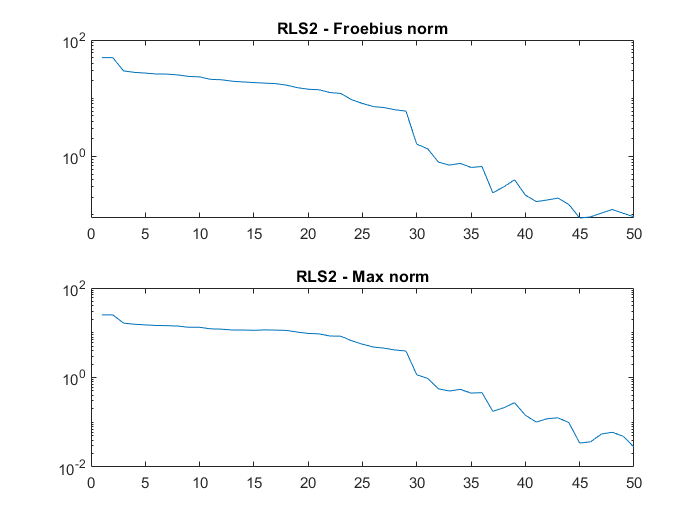

[rls2_foeb, rls2_max] = error_evolution(Y, Y2_hat, 'RLS2');

mpc_original = mpc;

## RLS with DoE

Finally, we integrate Design of Experiment into our framework

mpc_iteration = mpc_original;
mpopt_doe = mpoption('fmincon.alg', 6, 'opf.ac.solver', 'FMINCON', 'opf.start', 0);
line_sample = mpc_original.branch(1, :);
x_hat(:, 1) = 0.1 * ones([rls2_free_params, 1]);
Y_hat(:, :, 1) = reshape(Q * x_hat(:, 1), [n n]);
Z(:, :, 1) = 100 * eye(rls2_free_params);

for i = 2:samples
    mpc_iteration.bus(load_mask, PD) = load_pd(:, i);
    mpc_iteration.bus(load_mask, QD) = load_qd(:, i);
    
    mpc = mpc_iteration;
    mpc.branch = [];
    for j=1:n
        for k=j+1:n
            this_line = line_sample;
            this_line(1, F_BUS) = j;
            this_line(1, T_BUS) = k;
            this_line(1, BR_R) = - real(1 / Y_hat(j, k, i-1));
            this_line(1, BR_X) = - imag(1 / Y_hat(j, k, i-1));
            mpc.branch = [mpc.branch; this_line];
        end
    end
    Y_reconstruct = makeYbus(mpc);
    display(['Difference between estimated and reconstruced matrix ' num2str(max(max(abs(Y_hat(:, :, i-1) - Y_reconstruct))))]);
    res_doe = runopf_doe(mpc, mpopt_doe, Z(:, :, i-1), Q);
    V_star_ode(:, i) = res_doe.bus(:, VM);
    
    mpc = mpc_iteration;
    for j=1:length(controllable_mask)
        if controllable_mask(j)
            mpc.gen(mpc.gen(:, 1) == j, VG) = res_doe.bus(j, VM);
        end
    end
    res_pf = runpf(mpc);
    
    voltage_phase = res_pf.bus(:, VA) * pi / 180;
    voltage = res_pf.bus(:, VM).*(cos(voltage_phase) + sqrt(-1)*sin(voltage_phase))
    V_real_ode(:, i) = voltage + ev(:, i);
    I_real_ode(:, i) = Y * voltage + ei(:, i);
    
    [Y_hat(:, :, i), x_hat(:, i), Z(:, :, i)] = rls_step(V_real_ode(:, i), I_real_ode(:, i), Q, lambda, x_hat(:, i-1), Z(:, :, i-1));    
end

Difference between estimated and reconstruced matrix 0



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.523649e+01     1.219e+00     1.000e+00     0.000e+00     4.563e+01  
    1          38    6.104608e+01     1.034e+00     1.000e+00     2.823e+00     9.126e+03  
    2          60    6.219177e+01     1.003e+00     3.430e-01     3.579e+00     9.126e+03  
    3          83    6.248164e+01     9.155e-01     2.401e-01     1.021e+00     9.126e+03  
    4         105    6.197913e+01     9.853e-01     3.430e-01     1.030e+00     9.126e+03  
    5         128    6.175124e+01     9.578e-01     2.401e-01     9.006e-01     9.126e+03  
    6         152    6.163096e+01     9.054e-01     1.681e-01     5.567e-01     9.126e+03  
    7         175    6.148891e+01     9.270e-01     2.401


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    203.7             176.9
Loads              3     Load                   197.2             157.0
  Fixed            3       Fixed                197.2             157.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0484 - 0.0577i
   1.0675 - 0.0735i
   0.9953 - 0.0585i
   0.9862 - 0.0853i
   1.0101 - 0.1031i


Difference between estimated and reconstruced matrix 0



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.410874e+01     1.216e+00     1.000e+00     0.000e+00     4.546e+01  
    1          38    6.055830e+01     1.100e+00     1.000e+00     2.372e+00     9.092e+03  
    2          62    6.095013e+01     9.736e-01     1.681e-01     1.331e+00     9.092e+03  
    3          86    6.089245e+01     9.955e-01     1.681e-01     1.007e+00     9.092e+03  
    4         109    6.081924e+01     1.058e+00     2.401e-01     9.310e-01     9.092e+03  
    5         131    6.073444e+01     9.503e-01     3.430e-01     9.729e-01     9.092e+03  
    6         154    6.069372e+01     9.762e-01     2.401e-01     6.203e-01     9.092e+03  
    7         178    6.067164e+01     1.006e+00     1.681


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    227.8             145.9
Loads              3     Load                   220.8             124.7
  Fixed            3       Fixed                220.8             124.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0476 - 0.0705i
   1.0670 - 0.0801i
   0.9915 - 0.0848i
   0.9962 - 0.1037i
   1.0183 - 0.1072i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.483894e+01     1.050e+00     1.000e+00     0.000e+00     3.458e+01  
    1          38    6.342826e+01     3.676e-02     1.000e+00     1.217e+00     2.371e+01  
    2          57    6.332819e+01     1.162e-03     1.000e+00     2.006e-01     6.394e+00  
    3          76    6.305408e+01     1.057e-02     1.000e+00     5.153e-01     3.294e+00  
    4          95    6.299496e+01     1.176e-04     1.000e+00     6.403e-02     1.188e+00  
    5         114    6.299471e+01     1.237e-09     1.000e+00     2.204e-04     1.321e-02  
    6         133    6.299471e+01     4.968e-15     1.000e+00     1.418e-09     9.147e-07  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    221.3             182.8
Loads              3     Load                   211.8             151.1
  Fixed            3       Fixed                211.8             151.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9838 - 0.0434i
   1.0665 - 0.0867i
   0.9524 - 0.0620i
   0.9638 - 0.0885i
   0.9830 - 0.1110i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.276868e+01     1.116e+00     1.000e+00     0.000e+00     4.481e+01  
    1          38    6.147420e+01     5.259e-02     1.000e+00     1.596e+00     4.724e+01  
    2          57    6.150636e+01     1.790e-04     1.000e+00     1.161e-01     3.968e+00  
    3          76    6.150641e+01     6.482e-09     1.000e+00     5.878e-04     1.725e-02  
    4          95    6.150641e+01     3.775e-15     1.000e+00     2.123e-08     1.241e-06  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    206.5             168.4
Loads              3     Load                   198.1             142.0
  Fixed            3       Fixed                198.1             142.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0483 - 0.0593i
   0.9600 - 0.0351i
   0.9936 - 0.0626i
   0.9548 - 0.0764i
   0.9400 - 0.0802i


Difference between estimated and reconstruced matrix 1.831e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    5.940571e+01     1.356e+00     1.000e+00     0.000e+00     4.385e+01  
    1          38    6.118677e+01     7.554e-02     1.000e+00     1.588e+00     4.089e+01  
    2          57    6.100716e+01     2.400e-03     1.000e+00     3.058e-01     1.695e+01  
    3          76    6.076167e+01     4.993e-03     1.000e+00     3.397e-01     5.214e+00  
    4          95    6.076296e+01     1.789e-06     1.000e+00     6.445e-03     3.710e-01  
    5         114    6.076296e+01     8.438e-15     1.000e+00     2.272e-06     4.896e-05  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    231.1             185.8
Loads              3     Load                   222.2             158.1
  Fixed            3       Fixed                222.2             158.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0428 - 0.0755i
   0.9893 - 0.0662i
   0.9877 - 0.0803i
   0.9513 - 0.0976i
   0.9495 - 0.1046i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.362218e+01     1.167e+00     1.000e+00     0.000e+00     7.452e+01  
    1          38    6.332955e+01     7.200e-02     1.000e+00     1.376e+00     8.045e+01  
    2          57    6.242450e+01     4.710e-03     1.000e+00     5.426e-01     3.058e+01  
    3          76    6.199824e+01     4.350e-03     1.000e+00     4.004e-01     3.861e+00  
    4          95    6.199728e+01     1.063e-05     1.000e+00     2.266e-02     2.450e-01  
    5         114    6.199704e+01     4.902e-06     1.000e+00     1.460e-02     1.918e-01  
    6         133    6.199514e+01     1.445e-04     1.000e+00     7.918e-02     5.115e-01  
    7         152    6.199077e+01     3.941e-04     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    221.2             171.8
Loads              3     Load                   214.2             150.2
  Fixed            3       Fixed                214.2             150.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0478 - 0.0672i
   1.0673 - 0.0754i
   0.9894 - 0.0815i
   0.9907 - 0.0906i
   1.0104 - 0.1017i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.688050e+01     1.049e+00     1.000e+00     0.000e+00     4.649e+01  
    1          38    6.499022e+01     2.792e-02     1.000e+00     1.514e+00     4.068e+01  
    2          57    6.474755e+01     3.024e-03     1.000e+00     4.192e-01     1.761e+01  
    3          76    6.463422e+01     2.279e-03     1.000e+00     1.977e-01     1.247e+01  
    4          95    6.463325e+01     3.288e-07     1.000e+00     3.545e-03     1.466e-01  
    5         114    6.463325e+01     5.779e-15     1.000e+00     4.023e-07     7.746e-06  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    204.9             194.4
Loads              3     Load                   197.9             173.2
  Fixed            3       Fixed                197.9             173.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0484 - 0.0573i
   1.0678 - 0.0691i
   0.9938 - 0.0629i
   0.9795 - 0.0805i
   1.0049 - 0.0949i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.398026e+01     1.174e+00     1.000e+00     0.000e+00     6.769e+01  
    1          38    6.786222e+01     7.842e-02     1.000e+00     1.187e+00     5.213e+01  
    2          57    6.760789e+01     3.904e-03     1.000e+00     4.675e-01     2.885e+01  
    3          76    6.752544e+01     7.449e-04     1.000e+00     1.908e-01     3.310e+00  
    4          95    6.743220e+01     2.654e-03     1.000e+00     3.812e-01     3.534e+00  
    5         114    6.742737e+01     8.419e-06     1.000e+00     2.267e-02     2.532e-01  
    6         133    6.742737e+01     5.173e-12     1.000e+00     1.968e-05     7.708e-04  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    216.9             173.8
Loads              3     Load                   209.0             148.6
  Fixed            3       Fixed                209.0             148.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0351 - 0.0586i
   0.9717 - 0.0388i
   0.9831 - 0.0728i
   0.9467 - 0.0795i
   0.9411 - 0.0769i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.445183e+01     1.426e+00     1.000e+00     0.000e+00     4.901e+01  
    1          38    6.696533e+01     8.150e-02     1.000e+00     1.713e+00     4.708e+01  
    2          57    6.749010e+01     5.137e-03     1.000e+00     4.215e-01     1.536e+01  
    3          76    6.750378e+01     2.382e-06     1.000e+00     1.337e-02     1.187e-01  
    4          95    6.750378e+01     1.088e-14     1.000e+00     2.723e-06     2.468e-04  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    194.7             180.8
Loads              3     Load                   187.5             156.6
  Fixed            3       Fixed                187.5             156.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9835 - 0.0238i
   1.0334 - 0.0509i
   0.9585 - 0.0404i
   0.9486 - 0.0631i
   0.9598 - 0.0808i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.120898e+01     1.350e+00     1.000e+00     0.000e+00     4.356e+01  
    1          38    6.735141e+01     8.846e-02     1.000e+00     1.287e+00     3.548e+01  
    2          57    6.746811e+01     4.256e-03     1.000e+00     4.072e-01     1.721e+01  
    3          76    6.742827e+01     8.761e-04     1.000e+00     2.242e-01     1.834e+00  
    4          95    6.736605e+01     2.593e-03     1.000e+00     3.737e-01     1.255e+00  
    5         114    6.737384e+01     8.925e-07     1.000e+00     6.734e-03     1.687e-01  
    6         133    6.737384e+01     5.107e-15     1.000e+00     1.100e-06     6.155e-05  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    222.3             183.3
Loads              3     Load                   214.0             157.1
  Fixed            3       Fixed                214.0             157.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0340 - 0.0628i
   0.9762 - 0.0440i
   0.9762 - 0.0775i
   0.9459 - 0.0800i
   0.9437 - 0.0819i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.509172e+01     1.224e+00     1.000e+00     0.000e+00     8.154e+01  
    1          38    6.931788e+01     7.000e-02     1.000e+00     1.391e+00     3.969e+01  
    2          57    6.958515e+01     1.412e-03     1.000e+00     2.892e-01     2.366e+01  
    3          76    6.955354e+01     2.758e-04     1.000e+00     1.264e-01     7.876e+00  
    4          95    6.947309e+01     1.194e-03     1.000e+00     2.624e-01     4.088e+00  
    5         114    6.947486e+01     2.797e-07     1.000e+00     3.369e-03     1.436e-01  
    6         133    6.947486e+01     2.942e-15     1.000e+00     3.162e-07     2.594e-05  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    233.0             188.0
Loads              3     Load                   223.9             157.9
  Fixed            3       Fixed                223.9             157.9
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9906 - 0.0542i
   1.0426 - 0.0866i
   0.9561 - 0.0743i
   0.9507 - 0.0940i
   0.9649 - 0.1129i


Difference between estimated and reconstruced matrix 1.831e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.484450e+01     1.167e+00     1.000e+00     0.000e+00     7.715e+01  
    1          38    7.118473e+01     9.293e-02     1.000e+00     1.302e+00     8.757e+01  
    2          57    7.013623e+01     1.314e-02     1.000e+00     6.427e-01     6.315e+01  
    3          76    6.978100e+01     4.356e-03     1.000e+00     4.641e-01     1.346e+01  
    4          95    6.951007e+01     3.921e-03     1.000e+00     3.363e-01     1.044e+01  
    5         114    6.951413e+01     2.130e-06     1.000e+00     9.017e-03     8.254e-01  
    6         133    6.951413e+01     3.730e-14     1.000e+00     2.161e-06     2.421e-04  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    219.9             169.0
Loads              3     Load                   211.7             142.0
  Fixed            3       Fixed                211.7             142.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9872 - 0.0409i
   1.0479 - 0.0707i
   0.9553 - 0.0636i
   0.9581 - 0.0868i
   0.9766 - 0.0959i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.683889e+01     1.149e+00     1.000e+00     0.000e+00     9.082e+01  
    1          38    7.254774e+01     6.598e-02     1.000e+00     1.372e+00     9.193e+01  
    2          57    7.199572e+01     5.292e-03     1.000e+00     3.062e-01     4.708e+01  
    3          76    7.060900e+01     3.413e-02     1.000e+00     7.727e-01     3.102e+01  
    4          95    7.034177e+01     2.047e-03     1.000e+00     2.806e-01     8.103e+00  
    5         114    7.017226e+01     2.293e-03     1.000e+00     2.501e-01     8.700e+00  
    6         133    6.987256e+01     3.661e-03     1.000e+00     3.222e-01     5.867e+00  
    7         152    6.987110e+01     3.836e-06     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    225.3             173.7
Loads              3     Load                   217.9             151.0
  Fixed            3       Fixed                217.9             151.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0475 - 0.0719i
   1.0666 - 0.0853i
   0.9912 - 0.0814i
   0.9884 - 0.0970i
   1.0077 - 0.1132i


Difference between estimated and reconstruced matrix 1.831e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.591291e+01     1.518e+00     1.000e+00     0.000e+00     6.748e+01  
    1          38    7.219030e+01     1.243e-01     1.000e+00     1.139e+00     1.098e+02  
    2          57    7.195073e+01     5.011e-03     1.000e+00     4.961e-01     2.889e+01  
    3          76    7.163765e+01     4.928e-03     1.000e+00     3.829e-01     1.043e+01  
    4          95    7.146032e+01     3.118e-03     1.000e+00     2.276e-01     1.203e+01  
    5         114    7.140922e+01     1.020e-04     1.000e+00     3.536e-02     7.162e+00  
    6         133    7.135515e+01     1.290e-03     1.000e+00     1.586e-01     1.214e+01  
    7         152    7.106592e+01     4.414e-03     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    219.4             185.0
Loads              3     Load                   211.8             161.6
  Fixed            3       Fixed                211.8             161.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0477 - 0.0690i
   1.0664 - 0.0878i
   0.9973 - 0.0710i
   0.9791 - 0.0985i
   1.0031 - 0.1152i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.135278e+01     1.079e+00     1.000e+00     0.000e+00     1.405e+02  
    1          38    7.222994e+01     3.901e-02     1.000e+00     1.634e+00     7.485e+01  
    2          57    7.214470e+01     4.545e-03     1.000e+00     4.010e-01     1.563e+01  
    3          76    7.215499e+01     3.271e-06     1.000e+00     1.271e-02     8.702e-01  
    4          95    7.215500e+01     2.348e-14     1.000e+00     3.601e-06     2.094e-04  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    223.6             172.0
Loads              3     Load                   215.9             146.6
  Fixed            3       Fixed                215.9             146.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0128 - 0.0559i
   1.0667 - 0.0844i
   0.9718 - 0.0741i
   0.9761 - 0.0904i
   0.9945 - 0.1103i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.097533e+01     1.420e+00     1.000e+00     0.000e+00     8.001e+01  
    1          38    7.388699e+01     7.481e-02     1.000e+00     1.366e+00     1.143e+02  
    2          57    7.356102e+01     5.445e-03     1.000e+00     6.354e-01     1.384e+01  
    3          76    7.356921e+01     2.855e-06     1.000e+00     1.385e-02     9.365e-01  
    4          95    7.356921e+01     1.137e-13     1.000e+00     4.006e-06     2.322e-04  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    226.5             177.1
Loads              3     Load                   218.3             151.3
  Fixed            3       Fixed                218.3             151.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0384 - 0.0684i
   0.9862 - 0.0562i
   0.9857 - 0.0785i
   0.9535 - 0.0923i
   0.9472 - 0.0932i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.955775e+01     1.077e+00     1.000e+00     0.000e+00     1.177e+02  
    1          38    7.364605e+01     3.286e-02     1.000e+00     1.427e+00     7.360e+01  
    2          57    7.350695e+01     3.136e-04     1.000e+00     1.420e-01     2.607e+01  
    3          76    7.349784e+01     8.549e-05     1.000e+00     5.138e-02     3.616e+00  
    4          95    7.297084e+01     1.301e-02     1.000e+00     6.097e-01     1.619e+01  
    5         114    7.291104e+01     5.069e-05     1.000e+00     5.715e-02     2.456e+00  
    6         133    7.291027e+01     9.396e-06     1.000e+00     2.434e-02     1.339e+00  
    7         152    7.290543e+01     2.811e-04     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    201.9             159.9
Loads              3     Load                   196.2             142.2
  Fixed            3       Fixed                196.2             142.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0487 - 0.0531i
   1.0682 - 0.0625i
   0.9998 - 0.0639i
   0.9933 - 0.0812i
   1.0119 - 0.0894i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.707033e+01     1.479e+00     1.000e+00     0.000e+00     6.976e+01  
    1          38    7.587714e+01     1.010e-01     1.000e+00     1.448e+00     5.432e+01  
    2          57    7.560557e+01     8.009e-03     1.000e+00     3.924e-01     1.488e+02  
    3          76    7.551884e+01     6.218e-04     1.000e+00     1.852e-01     1.269e+01  
    4          95    7.524981e+01     4.513e-03     1.000e+00     4.832e-01     9.001e+00  
    5         114    7.525094e+01     9.311e-06     1.000e+00     1.837e-02     1.296e+00  
    6         133    7.524233e+01     5.381e-04     1.000e+00     1.215e-01     4.486e+00  
    7         152    7.524245e+01     3.338e-08     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    233.0             181.5
Loads              3     Load                   224.2             153.9
  Fixed            3       Fixed                224.2             153.9
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0389 - 0.0739i
   0.9879 - 0.0637i
   0.9854 - 0.0829i
   0.9470 - 0.0970i
   0.9503 - 0.1011i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.273375e+01     1.055e+00     1.000e+00     0.000e+00     1.411e+02  
    1          38    7.580905e+01     5.726e-02     1.000e+00     1.490e+00     5.389e+01  
    2          57    7.562623e+01     2.900e-03     1.000e+00     2.688e-01     4.622e+01  
    3          76    7.563151e+01     6.374e-07     1.000e+00     2.751e-03     7.891e-01  
    4          95    7.563151e+01     3.109e-14     1.000e+00     7.163e-07     6.212e-05  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    237.5             173.7
Loads              3     Load                   228.5             145.4
  Fixed            3       Fixed                228.5             145.4
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0363 - 0.0778i
   0.9788 - 0.0673i
   0.9824 - 0.0866i
   0.9503 - 0.0981i
   0.9438 - 0.1094i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.945557e+01     1.147e+00     1.000e+00     0.000e+00     8.373e+01  
    1          38    7.659455e+01     1.007e-01     1.000e+00     1.147e+00     1.279e+02  
    2          57    7.590450e+01     8.383e-03     1.000e+00     4.758e-01     6.341e+01  
    3          76    7.569523e+01     2.932e-03     1.000e+00     3.535e-01     1.107e+01  
    4          95    7.530963e+01     3.551e-03     1.000e+00     3.902e-01     9.179e+00  
    5         114    7.530748e+01     4.959e-05     1.000e+00     5.525e-02     4.744e+00  
    6         133    7.526168e+01     1.393e-03     1.000e+00     2.903e-01     5.194e+00  
    7         152    7.509268e+01     1.137e-02     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    232.0             175.7
Loads              3     Load                   224.0             151.3
  Fixed            3       Fixed                224.0             151.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0472 - 0.0761i
   1.0661 - 0.0911i
   0.9929 - 0.0855i
   0.9829 - 0.1050i
   1.0064 - 0.1174i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.839484e+01     1.426e+00     1.000e+00     0.000e+00     6.961e+01  
    1          38    7.583401e+01     9.217e-02     1.000e+00     1.469e+00     7.242e+01  
    2          57    7.622247e+01     2.954e-03     1.000e+00     2.641e-01     8.102e+01  
    3          76    7.605190e+01     2.790e-03     1.000e+00     3.751e-01     1.552e+01  
    4          95    7.567584e+01     1.005e-02     1.000e+00     7.160e-01     2.370e+00  
    5         114    7.572684e+01     6.241e-05     1.000e+00     5.674e-02     2.596e+00  
    6         133    7.572710e+01     1.771e-09     1.000e+00     2.968e-04     7.481e-03  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    244.4             173.8
Loads              3     Load                   235.1             145.1
  Fixed            3       Fixed                235.1             145.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0463 - 0.0884i
   1.0003 - 0.0855i
   0.9884 - 0.0898i
   0.9639 - 0.1133i
   0.9600 - 0.1258i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.296778e+01     1.119e+00     1.000e+00     0.000e+00     1.246e+02  
    1          38    7.621634e+01     7.226e-02     1.000e+00     1.278e+00     9.324e+01  
    2          57    7.569700e+01     8.509e-03     1.000e+00     5.373e-01     1.895e+01  
    3          76    7.541572e+01     2.480e-03     1.000e+00     2.668e-01     1.234e+01  
    4          95    7.542083e+01     2.362e-06     1.000e+00     1.068e-02     1.181e+00  
    5         114    7.541692e+01     1.961e-04     1.000e+00     7.384e-02     1.882e+00  
    6         133    7.540995e+01     2.311e-04     1.000e+00     8.040e-02     1.574e+00  
    7         152    7.541053e+01     6.277e-09     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    218.4             179.1
Loads              3     Load                   210.2             152.0
  Fixed            3       Fixed                210.2             152.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9893 - 0.0409i
   1.0474 - 0.0695i
   0.9530 - 0.0607i
   0.9566 - 0.0868i
   0.9756 - 0.0940i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.713962e+01     1.250e+00     1.000e+00     0.000e+00     6.441e+01  
    1          38    7.521239e+01     8.283e-02     1.000e+00     1.139e+00     1.431e+02  
    2          57    7.375000e+01     1.059e-02     1.000e+00     7.610e-01     5.494e+01  
    3          76    7.368789e+01     9.997e-04     1.000e+00     2.402e-01     6.243e+00  
    4          95    7.357275e+01     4.210e-03     1.000e+00     4.864e-01     6.654e+00  
    5         114    7.359040e+01     2.097e-06     1.000e+00     1.108e-02     2.296e+00  
    6         133    7.359040e+01     1.887e-14     1.000e+00     2.646e-06     1.869e-04  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    235.9             176.8
Loads              3     Load                   227.7             151.6
  Fixed            3       Fixed                227.7             151.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0470 - 0.0799i
   1.0657 - 0.0957i
   0.9914 - 0.0896i
   0.9866 - 0.1061i
   1.0033 - 0.1231i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.127160e+01     1.181e+00     1.000e+00     0.000e+00     1.255e+02  
    1          38    7.613864e+01     4.806e-02     1.000e+00     1.344e+00     2.445e+02  
    2          57    7.445303e+01     1.135e-02     1.000e+00     6.932e-01     7.064e+01  
    3          76    7.393545e+01     5.614e-03     1.000e+00     5.305e-01     1.942e+01  
    4          95    7.392350e+01     1.697e-06     1.000e+00     1.441e-02     2.714e-01  
    5         114    7.392350e+01     2.192e-13     1.000e+00     4.252e-06     1.135e-04  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    197.3             182.7
Loads              3     Load                   191.2             164.2
  Fixed            3       Fixed                191.2             164.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0489 - 0.0489i
   1.0687 - 0.0526i
   0.9922 - 0.0620i
   0.9890 - 0.0716i
   1.0092 - 0.0763i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.282644e+01     1.185e+00     1.000e+00     0.000e+00     1.413e+02  
    1          38    7.628585e+01     4.405e-02     1.000e+00     1.343e+00     3.075e+02  
    2          57    7.518941e+01     1.496e-02     1.000e+00     7.851e-01     2.120e+01  
    3          76    7.472481e+01     2.435e-03     1.000e+00     2.255e-01     1.760e+01  
    4          95    7.472793e+01     3.347e-07     1.000e+00     2.716e-03     1.624e-01  
    5         114    7.472793e+01     4.288e-15     1.000e+00     7.896e-07     2.293e-05  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    203.5             168.0
Loads              3     Load                   196.6             145.9
  Fixed            3       Fixed                196.6             145.9
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0310 - 0.0483i
   0.9729 - 0.0299i
   0.9775 - 0.0618i
   0.9486 - 0.0640i
   0.9481 - 0.0717i


Difference between estimated and reconstruced matrix 8.8818e-16



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.911083e+01     1.280e+00     1.000e+00     0.000e+00     1.032e+02  
    1          38    7.608550e+01     1.155e-01     1.000e+00     1.220e+00     4.509e+01  
    2          57    7.526291e+01     5.502e-03     1.000e+00     3.782e-01     1.792e+02  
    3          76    7.445617e+01     5.924e-03     1.000e+00     4.184e-01     3.465e+01  
    4          95    7.436353e+01     9.031e-04     1.000e+00     2.262e-01     9.483e+00  
    5         114    7.431833e+01     2.593e-04     1.000e+00     1.150e-01     3.642e+00  
    6         133    7.430699e+01     2.021e-04     1.000e+00     9.565e-02     5.245e+00  
    7         152    7.420417e+01     5.354e-03     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    212.6             183.0
Loads              3     Load                   204.7             156.8
  Fixed            3       Fixed                204.7             156.8
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9901 - 0.0372i
   1.0443 - 0.0639i
   0.9562 - 0.0571i
   0.9512 - 0.0796i
   0.9727 - 0.0890i


Difference between estimated and reconstruced matrix 7.1054e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.820303e+01     1.360e+00     1.000e+00     0.000e+00     8.396e+01  
    1          38    7.495761e+01     7.135e-02     1.000e+00     1.185e+00     1.168e+02  
    2          57    7.391406e+01     6.560e-03     1.000e+00     4.809e-01     7.016e+01  
    3          76    7.388118e+01     4.860e-04     1.000e+00     1.750e-01     1.362e+01  
    4          95    7.377597e+01     2.063e-03     1.000e+00     3.548e-01     7.286e+00  
    5         114    7.377743e+01     9.669e-07     1.000e+00     6.095e-03     7.165e-01  
    6         133    7.377743e+01     3.275e-15     1.000e+00     1.091e-06     1.650e-04  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    240.0             180.0
Loads              3     Load                   231.2             152.7
  Fixed            3       Fixed                231.2             152.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0467 - 0.0834i
   1.0647 - 0.1062i
   0.9967 - 0.0853i
   0.9791 - 0.1204i
   0.9999 - 0.1323i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.671528e+01     1.455e+00     1.000e+00     0.000e+00     7.672e+01  
    1          38    7.436317e+01     6.335e-02     1.000e+00     1.459e+00     8.485e+01  
    2          57    7.376516e+01     2.416e-03     1.000e+00     2.764e-01     6.572e+01  
    3          76    7.377107e+01     6.421e-07     1.000e+00     5.496e-03     1.057e+00  
    4          95    7.377107e+01     5.115e-14     1.000e+00     1.850e-06     2.856e-04  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.01 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    201.4             175.6
Loads              3     Load                   194.6             154.1
  Fixed            3       Fixed                194.6             154.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0356 - 0.0490i
   0.9841 - 0.0338i
   0.9857 - 0.0616i
   0.9536 - 0.0642i
   0.9479 - 0.0729i


Difference between estimated and reconstruced matrix 1.986e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.994454e+01     1.161e+00     1.000e+00     0.000e+00     1.123e+02  
    1          38    7.316768e+01     5.947e-02     1.000e+00     1.409e+00     5.146e+01  
    2          57    7.350617e+01     5.361e-03     1.000e+00     3.528e-01     1.689e+01  
    3          76    7.344840e+01     2.953e-04     1.000e+00     8.399e-02     3.327e+00  
    4          95    7.344809e+01     8.877e-06     1.000e+00     1.881e-02     6.394e-01  
    5         114    7.344333e+01     2.571e-04     1.000e+00     1.015e-01     7.428e-01  
    6         133    7.338953e+01     5.777e-03     1.000e+00     4.816e-01     5.989e+00  
    7         152    7.340351e+01     3.718e-05     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    198.6             178.8
Loads              3     Load                   191.5             155.2
  Fixed            3       Fixed                191.5             155.2
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9854 - 0.0233i
   1.0395 - 0.0405i
   0.9501 - 0.0500i
   0.9602 - 0.0623i
   0.9673 - 0.0650i


Difference between estimated and reconstruced matrix 3.6621e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.374458e+01     1.978e+00     1.000e+00     0.000e+00     5.589e+01  
    1          38    7.316373e+01     1.718e-01     1.000e+00     1.061e+00     1.116e+02  
    2          57    7.320571e+01     1.124e-02     1.000e+00     6.741e-01     1.007e+02  
    3          76    7.309424e+01     8.894e-04     1.000e+00     2.677e-01     8.718e+00  
    4          95    7.292977e+01     4.083e-03     1.000e+00     4.822e-01     2.959e+01  
    5         114    7.281504e+01     1.619e-03     1.000e+00     3.034e-01     8.690e+00  
    6         133    7.281626e+01     3.057e-07     1.000e+00     4.257e-03     5.953e-01  
    7         152    7.281626e+01     4.774e-15     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    238.2             174.0
Loads              3     Load                   229.1             145.7
  Fixed            3       Fixed                229.1             145.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0389 - 0.0777i
   0.9829 - 0.0668i
   0.9870 - 0.0870i
   0.9508 - 0.1035i
   0.9451 - 0.1051i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.574117e+01     1.375e+00     1.000e+00     0.000e+00     7.560e+01  
    1          38    7.221121e+01     9.363e-02     1.000e+00     1.377e+00     9.737e+01  
    2          57    7.240065e+01     1.079e-03     1.000e+00     2.784e-01     3.061e+01  
    3          76    7.237335e+01     5.590e-04     1.000e+00     9.694e-02     8.078e+00  
    4          95    7.207592e+01     5.554e-03     1.000e+00     2.745e-01     1.671e+01  
    5         114    7.205030e+01     2.718e-04     1.000e+00     1.043e-01     1.153e+01  
    6         133    7.185774e+01     8.691e-03     1.000e+00     5.883e-01     3.517e+01  
    7         152    7.171335e+01     1.026e-03     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    205.1             168.5
Loads              3     Load                   198.9             149.4
  Fixed            3       Fixed                198.9             149.4
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0485 - 0.0553i
   1.0680 - 0.0652i
   0.9985 - 0.0652i
   0.9860 - 0.0839i
   1.0119 - 0.0909i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.170129e+01     1.090e+00     1.000e+00     0.000e+00     1.403e+02  
    1          38    7.367798e+01     3.609e-02     1.000e+00     1.208e+00     9.585e+01  
    2          57    7.359807e+01     3.430e-05     1.000e+00     5.465e-02     2.009e+00  
    3          76    7.359784e+01     1.539e-06     1.000e+00     9.911e-03     4.572e-01  
    4          95    7.359716e+01     4.209e-05     1.000e+00     5.177e-02     5.786e-01  
    5         114    7.359197e+01     9.922e-04     1.000e+00     2.511e-01     7.515e-01  
    6         133    7.359182e+01     2.214e-08     1.000e+00     2.169e-03     4.404e-01  
    7         152    7.359182e+01     7.772e-15     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    222.6             161.3
Loads              3     Load                   214.7             136.5
  Fixed            3       Fixed                214.7             136.5
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0358 - 0.0629i
   0.9748 - 0.0450i
   0.9837 - 0.0768i
   0.9526 - 0.0874i
   0.9471 - 0.0840i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.753948e+01     1.512e+00     1.000e+00     0.000e+00     7.271e+01  
    1          38    7.446145e+01     9.673e-02     1.000e+00     1.520e+00     8.185e+01  
    2          57    7.489486e+01     3.176e-03     1.000e+00     2.609e-01     6.825e+01  
    3          76    7.487108e+01     4.689e-04     1.000e+00     1.542e-01     8.655e+00  
    4          95    7.470069e+01     5.785e-03     1.000e+00     5.373e-01     1.543e+01  
    5         114    7.471811e+01     1.301e-05     1.000e+00     2.180e-02     7.217e+00  
    6         133    7.471810e+01     1.841e-13     1.000e+00     1.268e-05     6.132e-03  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    208.2             174.5
Loads              3     Load                   201.8             154.3
  Fixed            3       Fixed                201.8             154.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0483 - 0.0597i
   1.0674 - 0.0739i
   0.9982 - 0.0652i
   0.9873 - 0.0878i
   1.0067 - 0.1015i


Difference between estimated and reconstruced matrix 3.6621e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.167326e+01     1.129e+00     1.000e+00     0.000e+00     1.351e+02  
    1          38    7.575836e+01     3.021e-02     1.000e+00     1.225e+00     4.887e+01  
    2          57    7.522255e+01     3.445e-03     1.000e+00     3.576e-01     3.954e+01  
    3          76    7.499534e+01     5.153e-04     1.000e+00     1.523e-01     5.435e+00  
    4          95    7.498887e+01     7.081e-05     1.000e+00     6.741e-02     3.848e+00  
    5         114    7.495018e+01     2.078e-03     1.000e+00     3.624e-01     4.817e+00  
    6         133    7.492848e+01     3.164e-04     1.000e+00     1.409e-01     1.709e+00  
    7         152    7.492802e+01     2.160e-09     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    229.4             160.4
Loads              3     Load                   222.1             137.7
  Fixed            3       Fixed                222.1             137.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0473 - 0.0751i
   1.0661 - 0.0913i
   0.9963 - 0.0847i
   0.9926 - 0.1034i
   1.0068 - 0.1206i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.883189e+01     1.138e+00     1.000e+00     0.000e+00     7.620e+01  
    1          38    7.544509e+01     8.685e-02     1.000e+00     1.375e+00     7.972e+01  
    2          57    7.540399e+01     1.123e-02     1.000e+00     5.460e-01     3.983e+01  
    3          76    7.539974e+01     2.216e-04     1.000e+00     9.426e-02     6.584e+00  
    4          95    7.540038e+01     8.678e-09     1.000e+00     6.148e-04     5.164e-02  
    5         114    7.540038e+01     3.414e-15     1.000e+00     8.721e-09     5.115e-06  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    218.6             180.8
Loads              3     Load                   210.4             153.8
  Fixed            3       Fixed                210.4             153.8
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9897 - 0.0426i
   1.0475 - 0.0709i
   0.9517 - 0.0643i
   0.9582 - 0.0800i
   0.9753 - 0.0980i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.105222e+01     1.053e+00     1.000e+00     0.000e+00     1.192e+02  
    1          38    7.620958e+01     5.389e-02     1.000e+00     1.100e+00     9.734e+01  
    2          57    7.539228e+01     8.116e-03     1.000e+00     5.088e-01     5.717e+01  
    3          76    7.494052e+01     6.159e-03     1.000e+00     6.462e-01     3.365e+01  
    4          95    7.471219e+01     1.268e-03     1.000e+00     3.156e-01     4.232e+00  
    5         114    7.471496e+01     7.884e-08     1.000e+00     2.742e-03     2.751e-01  
    6         133    7.471496e+01     4.219e-15     1.000e+00     1.503e-07     9.908e-05  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    232.3             162.5
Loads              3     Load                   224.7             138.7
  Fixed            3       Fixed                224.7             138.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0471 - 0.0785i
   1.0655 - 0.0979i
   0.9982 - 0.0866i
   0.9914 - 0.1051i
   1.0035 - 0.1286i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.879184e+01     1.556e+00     1.000e+00     0.000e+00     7.763e+01  
    1          38    7.730464e+01     4.360e-02     1.000e+00     1.411e+00     4.000e+01  
    2          57    7.676876e+01     2.739e-03     1.000e+00     2.738e-01     1.025e+02  
    3          76    7.625257e+01     8.319e-03     1.000e+00     5.987e-01     4.589e+01  
    4          95    7.587075e+01     3.754e-03     1.000e+00     3.033e-01     2.628e+01  
    5         114    7.567641e+01     1.399e-03     1.000e+00     1.663e-01     3.096e+01  
    6         133    7.540128e+01     1.218e-03     1.000e+00     1.581e-01     2.852e+01  
    7         152    7.540045e+01     1.845e-08     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    207.1             170.1
Loads              3     Load                   199.9             147.6
  Fixed            3       Fixed                199.9             147.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0322 - 0.0506i
   0.9756 - 0.0323i
   0.9784 - 0.0645i
   0.9498 - 0.0692i
   0.9480 - 0.0719i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.880673e+01     1.176e+00     1.000e+00     0.000e+00     8.988e+01  
    1          38    7.529529e+01     7.560e-02     1.000e+00     1.499e+00     2.026e+02  
    2          57    7.435560e+01     1.850e-03     1.000e+00     2.406e-01     3.281e+01  
    3          76    7.435661e+01     5.633e-05     1.000e+00     5.293e-02     3.365e+00  
    4          95    7.432681e+01     1.407e-03     1.000e+00     2.662e-01     2.337e+00  
    5         114    7.425141e+01     5.172e-03     1.000e+00     5.073e-01     3.484e+00  
    6         133    7.426436e+01     1.393e-05     1.000e+00     2.274e-02     1.979e+00  
    7         152    7.426436e+01     1.505e-13     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    211.7             170.3
Loads              3     Load                   205.3             150.3
  Fixed            3       Fixed                205.3             150.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0482 - 0.0609i
   1.0676 - 0.0720i
   0.9997 - 0.0728i
   0.9910 - 0.0870i
   1.0041 - 0.0980i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.383380e+01     1.216e+00     1.000e+00     0.000e+00     1.232e+02  
    1          38    7.580669e+01     8.133e-02     1.000e+00     1.226e+00     1.810e+02  
    2          57    7.440802e+01     1.846e-02     1.000e+00     7.359e-01     4.093e+01  
    3          76    7.440788e+01     4.547e-04     1.000e+00     9.742e-02     7.703e+00  
    4          95    7.440753e+01     3.046e-09     1.000e+00     3.962e-04     1.307e-02  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    241.8             181.4
Loads              3     Load                   232.9             154.1
  Fixed            3       Fixed                232.9             154.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0466 - 0.0845i
   1.0650 - 0.1037i
   0.9926 - 0.0916i
   0.9776 - 0.1130i
   1.0035 - 0.1308i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.407857e+01     1.245e+00     1.000e+00     0.000e+00     1.087e+02  
    1          38    7.627235e+01     8.169e-02     1.000e+00     1.320e+00     1.736e+02  
    2          57    7.558340e+01     4.315e-03     1.000e+00     4.199e-01     3.941e+01  
    3          76    7.538914e+01     3.138e-03     1.000e+00     3.960e-01     2.184e+00  
    4          95    7.532009e+01     5.043e-04     1.000e+00     1.602e-01     2.157e+00  
    5         114    7.532284e+01     1.192e-07     1.000e+00     2.039e-03     2.266e-01  
    6         133    7.532284e+01     2.665e-15     1.000e+00     1.190e-07     1.441e-05  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    223.6             172.6
Loads              3     Load                   215.2             144.4
  Fixed            3       Fixed                215.2             144.4
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9771 - 0.0389i
   1.0299 - 0.0647i
   0.9494 - 0.0671i
   0.9470 - 0.0840i
   0.9567 - 0.0906i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.661012e+01     1.472e+00     1.000e+00     0.000e+00     6.605e+01  
    1          38    7.530618e+01     1.048e-01     1.000e+00     1.286e+00     1.287e+02  
    2          57    7.419081e+01     8.743e-03     1.000e+00     5.389e-01     1.381e+02  
    3          76    7.411691e+01     6.198e-04     1.000e+00     1.985e-01     1.691e+01  
    4          95    7.411719e+01     8.584e-08     1.000e+00     1.813e-03     1.900e-01  
    5         114    7.411719e+01     5.329e-15     1.000e+00     9.555e-08     1.306e-05  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    208.4             173.1
Loads              3     Load                   201.2             150.3
  Fixed            3       Fixed                201.2             150.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0357 - 0.0526i
   0.9815 - 0.0356i
   0.9857 - 0.0666i
   0.9480 - 0.0722i
   0.9494 - 0.0729i


Difference between estimated and reconstruced matrix 3.9721e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.668205e+01     1.294e+00     1.000e+00     0.000e+00     7.406e+01  
    1          38    7.505801e+01     7.399e-02     1.000e+00     1.259e+00     1.351e+02  
    2          57    7.469291e+01     3.242e-03     1.000e+00     3.991e-01     1.593e+02  
    3          76    7.445647e+01     2.554e-03     1.000e+00     3.264e-01     3.393e+01  
    4          95    7.444245e+01     3.003e-05     1.000e+00     4.194e-02     1.350e+01  
    5         114    7.441770e+01     5.358e-04     1.000e+00     1.808e-01     1.257e+01  
    6         133    7.438915e+01     6.079e-04     1.000e+00     1.927e-01     4.817e+00  
    7         152    7.439153e+01     7.376e-08     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    217.0             178.2
Loads              3     Load                   208.7             150.8
  Fixed            3       Fixed                208.7             150.8
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9892 - 0.0408i
   1.0479 - 0.0725i
   0.9542 - 0.0569i
   0.9549 - 0.0883i
   0.9773 - 0.0982i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.621581e+01     1.302e+00     1.000e+00     0.000e+00     8.141e+01  
    1          38    7.223573e+01     5.846e-02     1.000e+00     1.361e+00     8.470e+01  
    2          57    7.240974e+01     1.147e-03     1.000e+00     2.610e-01     6.427e+00  
    3          76    7.240511e+01     3.443e-05     1.000e+00     4.636e-02     1.347e+00  
    4          95    7.238627e+01     1.072e-03     1.000e+00     2.401e-01     1.507e+00  
    5         114    7.236477e+01     8.037e-04     1.000e+00     1.709e-01     5.521e+00  
    6         133    7.236031e+01     1.297e-05     1.000e+00     1.255e-02     6.595e+00  
    7         152    7.230300e+01     4.576e-04     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    212.7             171.9
Loads              3     Load                   205.9             151.5
  Fixed            3       Fixed                205.9             151.5
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0483 - 0.0605i
   1.0679 - 0.0674i
   0.9925 - 0.0756i
   0.9843 - 0.0818i
   1.0143 - 0.0936i


Difference between estimated and reconstruced matrix 1.7764e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.891473e+01     1.099e+00     1.000e+00     0.000e+00     9.563e+01  
    1          38    7.458864e+01     6.305e-02     1.000e+00     1.169e+00     1.363e+02  
    2          57    7.438152e+01     2.112e-03     1.000e+00     2.732e-01     5.845e+01  
    3          76    7.433535e+01     3.246e-04     1.000e+00     1.259e-01     9.445e+00  
    4          95    7.377481e+01     1.016e-02     1.000e+00     6.638e-01     2.205e+01  
    5         114    7.375561e+01     2.698e-04     1.000e+00     1.131e-01     1.208e+01  
    6         133    7.349229e+01     7.340e-03     1.000e+00     6.019e-01     1.626e+01  
    7         152    7.333877e+01     2.099e-03     1.000


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    213.2             161.1
Loads              3     Load                   206.7             141.0
  Fixed            3       Fixed                206.7             141.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0481 - 0.0629i
   1.0671 - 0.0783i
   1.0049 - 0.0721i
   0.9878 - 0.0910i
   1.0065 - 0.1067i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.120432e+01     1.288e+00     1.000e+00     0.000e+00     1.104e+02  
    1          38    7.432297e+01     4.989e-02     1.000e+00     1.536e+00     1.461e+02  
    2          57    7.368196e+01     9.174e-03     1.000e+00     5.672e-01     5.088e+01  
    3          76    7.345059e+01     1.762e-03     1.000e+00     3.055e-01     9.029e+00  
    4          95    7.345158e+01     1.440e-06     1.000e+00     7.309e-03     4.805e-01  
    5         114    7.345158e+01     2.887e-15     1.000e+00     1.348e-06     5.264e-05  

Local minimum found that satisfies the constraints.

Optimization comple


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    212.8             196.3
Loads              3     Load                   205.1             171.6
  Fixed            3       Fixed                205.1             171.6
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0194 - 0.0502i
   1.0676 - 0.0718i
   0.9679 - 0.0640i
   0.9688 - 0.0810i
   0.9985 - 0.0954i


Difference between estimated and reconstruced matrix 3.6621e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.483508e+01     1.156e+00     1.000e+00     0.000e+00     1.018e+02  
    1          38    7.477498e+01     2.189e-02     1.000e+00     1.483e+00     1.298e+02  
    2          57    7.458471e+01     4.240e-03     1.000e+00     4.846e-01     2.728e+01  
    3          76    7.460448e+01     2.036e-06     1.000e+00     1.098e-02     9.042e-01  
    4          95    7.460448e+01     1.910e-14     1.000e+00     2.554e-06     2.059e-04  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    218.2             166.3
Loads              3     Load                   210.4             141.7
  Fixed            3       Fixed                210.4             141.7
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0324 - 0.0604i
   0.9727 - 0.0471i
   0.9788 - 0.0673i
   0.9486 - 0.0864i
   0.9466 - 0.0891i


Difference between estimated and reconstruced matrix 2.5121e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.837680e+01     1.349e+00     1.000e+00     0.000e+00     7.999e+01  
    1          38    7.395529e+01     8.270e-02     1.000e+00     1.435e+00     1.381e+02  
    2          57    7.340405e+01     5.730e-03     1.000e+00     2.760e-01     5.344e+01  
    3          76    7.333462e+01     9.180e-04     1.000e+00     2.058e-01     1.239e+01  
    4          95    7.289904e+01     1.769e-02     1.000e+00     9.421e-01     6.118e+00  
    5         114    7.299184e+01     1.264e-04     1.000e+00     6.817e-02     8.787e+00  
    6         133    7.299187e+01     2.952e-11     1.000e+00     1.192e-04     5.319e-03  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    210.7             167.8
Loads              3     Load                   203.0             142.1
  Fixed            3       Fixed                203.0             142.1
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   0.9861 - 0.0346i
   1.0491 - 0.0635i
   0.9517 - 0.0560i
   0.9638 - 0.0779i
   0.9792 - 0.0906i


Difference between estimated and reconstruced matrix 3.6621e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    7.011391e+01     1.321e+00     1.000e+00     0.000e+00     1.153e+02  
    1          38    7.325912e+01     2.454e-02     1.000e+00     1.474e+00     7.378e+01  
    2          57    7.311147e+01     1.396e-03     1.000e+00     2.831e-01     1.611e+01  
    3          76    7.311405e+01     2.017e-07     1.000e+00     3.528e-03     3.428e-01  
    4          95    7.311405e+01     1.889e-15     1.000e+00     2.548e-07     3.309e-05  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 



MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    211.3             158.3
Loads              3     Load                   205.2             139.3
  Fixed            3       Fixed                205.2             139.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0484 - 0.0580i
   1.0680 - 0.0647i
   0.9998 - 0.0747i
   0.9920 - 0.0869i
   1.0108 - 0.0889i


Difference between estimated and reconstruced matrix 3.5527e-15



MATPOWER Version 7.0, 20-Jun-2019 -- AC Optimal Power Flow
  AC OPF formulation: polar voltages, power balance eqns
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          19    6.739241e+01     1.241e+00     1.000e+00     0.000e+00     6.210e+01  
    1          38    7.414848e+01     6.623e-02     1.000e+00     1.261e+00     9.194e+01  
    2          57    7.365226e+01     1.849e-03     1.000e+00     2.958e-01     2.971e+01  
    3          76    7.360724e+01     8.694e-04     1.000e+00     2.224e-01     3.128e+00  
    4          95    7.353773e+01     1.488e-03     1.000e+00     2.893e-01     1.849e+00  
    5         114    7.354278e+01     2.653e-07     1.000e+00     3.900e-03     2.023e-01  
    6         133    7.354278e+01     5.329e-15     1.000e+00     3.325e-07     2.998e-05  




MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.00 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              6     Total Gen Capacity     530.0        -300.0 to 300.0
Generators         3     On-line Capacity       530.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    214.6             159.1
Loads              3     Load                   207.1             135.4
  Fixed            3       Fixed                207.1             135.4
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

voltage =    1.0500 + 0.0000i
   1.0354 - 0.0590i
   0.9730 - 0.0439i
   0.9878 - 0.0705i
   0.9494 - 0.0779i
   0.9467 - 0.0872i


Froebius norm for DoE is 0.060401
Max norm for DoE is 0.026605


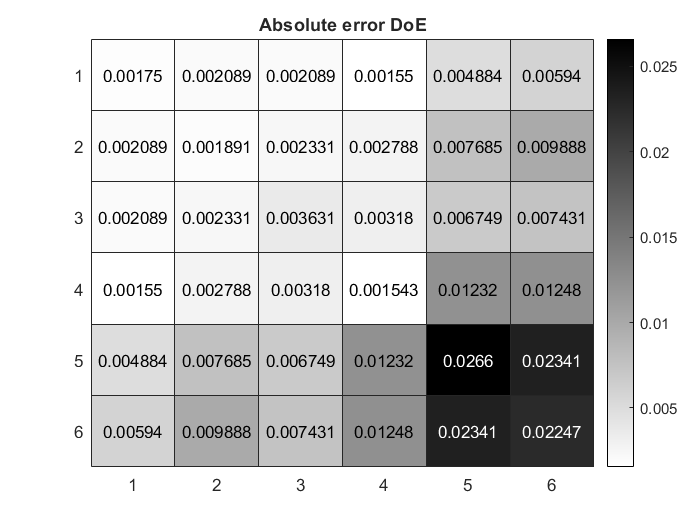

error_metrics(Y, Y_hat(:, :, end), 'DoE');

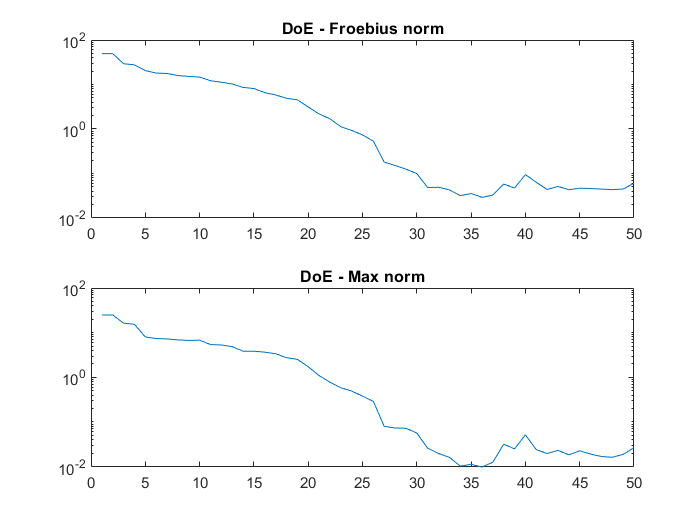

[doe_foeb, doe_max] = error_evolution(Y, Y_hat, 'DoE');

## Comparison between methods

Finally, we compare error evolution between the two methods

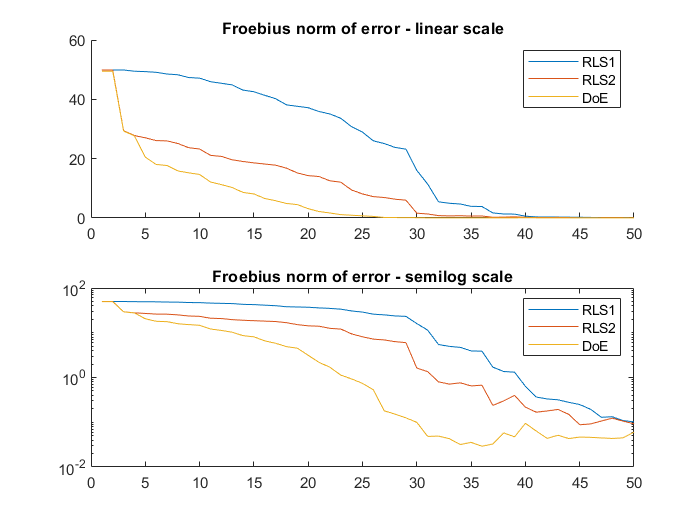

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_foeb);
plot(1:samples, rls2_foeb);
plot(1:samples, doe_foeb);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_foeb; rls2_foeb; doe_foeb]');
legend('RLS1', 'RLS2', 'DoE');
title('Froebius norm of error - semilog scale');

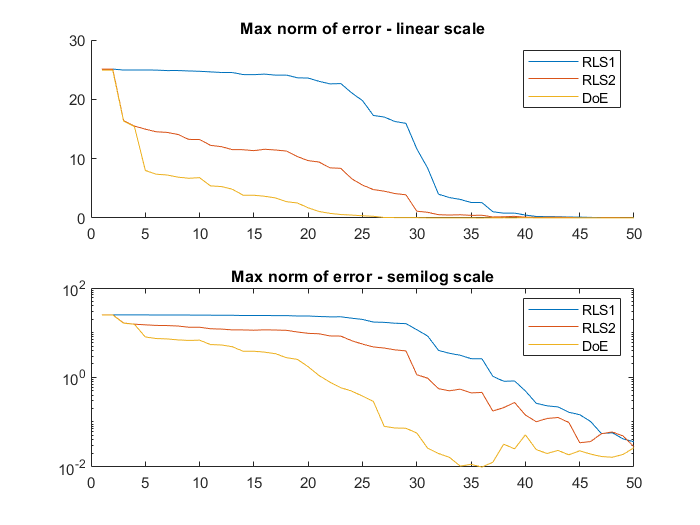

figure()
subplot(2, 1, 1)
hold on
plot(1:samples, rls1_max);
plot(1:samples, rls2_max);
plot(1:samples, doe_max);
hold off
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - linear scale');
subplot(2, 1, 2)
semilogy([rls1_max; rls2_max; doe_max]');
legend('RLS1', 'RLS2', 'DoE');
title('Max norm of error - semilog scale');